clear
x=readmatrix('1题.xlsx','Range','B2:E28');
name=readcell("1题.xlsx",'Range','A2:A28');
kmo=KMO(x)

kmo = 0.8246

[ndim,prob,chisquare]=barttest(x)   %kmo和bartlett检验适合主成分分析

ndim = 4

prob =     0.0000
    0.0000
    0.0221


chisquare =   750.8211
  184.8615
    7.6248


x_stander=zscore(x);
r=corrcoef(x_stander);
[vec1,lamda,rate]=pcacov(r); %lamda是r的特征值，rate是各主成分贡献率
lamda

lamda =     3.3770
    0.3943
    0.1656
    0.0631


contr=cumsum(rate)

contr =    84.4248
   94.2821
   98.4220
  100.0000


f=repmat(sign(sum(vec1)),size(vec1,1),1);  %构造与vec1同维的元素为正负1的矩阵
vec2=vec1.*f;  %修改特征向量的正负号，使每个特征向量的分量和为正
num=2;  %选两个主成分个数
vec2(:,1:num);
df=x*vec2(:,1:num);  %各主成分得分
tf=df*rate(1:num)/500000; %综合得分
%tf=zscore(tf);
[stf,ind]=sort(tf,'descend');
stf,ind;

stf =    66.7937
   59.5426
   55.1210
   40.4368
   36.6196
   28.6253
   27.0853
   24.4927
   21.1617
   20.0940


for i=1:length(name)
    xname(i)=name(ind(i));
end

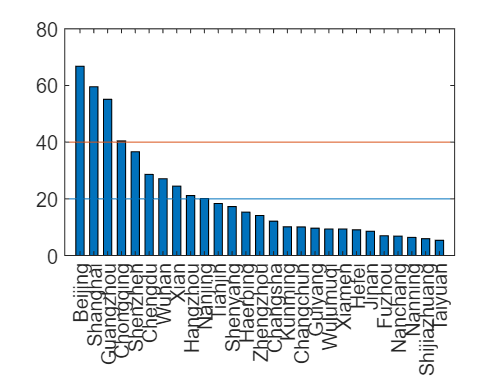

bar(stf,0.6)
%axis([0.3 10.8 0 80]);
set(gca,'XTick',1:27,'XTickLabel',xname)
%ylabel("Comprehensive Score");
hold on
line([[0,0];[28,28]],[[20,40];[20,40]])
hold off

function kmo=KMO(SA)
    X=corrcoef(SA);%SA是样本的原始数据
    iX = inv(X);     %X是原始数据的相关系数矩阵R，而inv表示求X的逆矩阵iX
    S2 = diag(diag((iX.^-1)));    %将iX的对角线的元素取倒数，其余元素都变为0，得到矩阵S2
    AIS = S2*iX*S2;    %anti-image covariance matrix，即AIS是反映像协方差矩阵   
    IS = X+AIS-2*S2;    %image covariance matrix，即IS是映像协方差矩阵
    Dai = diag(diag(sqrt(AIS)));    %就是将矩阵AIS对角线上的元素开平方，并且将其余元素都变成0，得到矩阵Dai
    IR = inv(Dai)*IS*inv(Dai); %image correlation matrix，即IR是映像相关矩阵
    AIR = inv(Dai)*AIS*inv(Dai); %anti-image correlation matrix，即AIR是反映像相关矩阵
    a = sum((AIR - diag(diag(AIR))).^2);    %diag(diag(AIR))表示将矩阵AIR的对角线取出来，再构造成一个对角矩阵（即对角线之   外元素都是 0）；. 表示将偏相关系数矩阵AIR - diag(diag(AIR))的每一个元素乘方，这样得到矩阵a。
    AA = sum(a);              %得到偏相关系数矩阵AIR - diag(diag(AIR))中所有偏相关系数的平方和AA，但不考虑其对角线上的数值。
    b = sum((X - eye(size(X))).^2);    %eye（）是单位矩阵；b就是将相关系数矩阵R中每一个元素乘方，但R对角线元素全部变成0
    BB = sum(b);             %BB就是所有变量之间（不包括变量自己与自己）的相关系数的平方和。
    kmo = BB/(AA+BB);   %KMO就是所有变量之间相关系数的平方和除以它与所有变量之间偏相关系数平方和的商，但不考虑变量  自己与自己的相关系数1以及偏相关系数。
end